clc;clear all;close all;
Ts=0.01%Periodo de muestreo

Ts = 0.0100

OS=20%

OS = 20

ts5=4%tiempo establecimiento

ts5 = 4

xi=log(100/OS)/sqrt(pi^2+log(100/OS)^2)

xi = 0.4559

%ts=3.2/(xi*wn)
wn=3.2/(xi*ts5)

wn = 1.7546

s1=-xi*wn+sqrt(1-xi^2)*wn*i

s1 = -0.8000 + 1.5616i

s2=-xi*wn-sqrt(1-xi^2)*wn*i

s2 = -0.8000 - 1.5616i

z1=exp(s1*Ts)

z1 = 0.9919 + 0.0155i

z2=exp(s2*Ts)

z2 = 0.9919 - 0.0155i

s=tf('s');
z=tf('z',Ts);
Gs=1/(s^2+3*s+1)


Gs =
 
        1
  -------------
  s^2 + 3 s + 1
 
Continuous-time transfer function.
Model Properties


Gz=c2d(Gs,Ts,'zoh')


Gz =
 
  4.95e-05 z + 4.901e-05
  ----------------------
  z^2 - 1.97 z + 0.9704
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


ki=5;% de ess
%
%1+Kz*Gz=0 en z=..., hallas kp y kd
%1+Kz*Gz=0 en z=...
syms kp kd real
syms z
wc=1000;
Kz=(kp+ki*Ts/2*(z+1)/(z-1)+kd*1/(1/wc+(Ts/2*(z+1)/(z-1))));
Gzeval=evalfr(Gz,z1)

Gzeval = -0.2151 - 0.1446i

Kzeval=subs(Kz,z,z1)

$$Kzeval = \mathrm{kp}+\mathrm{kd}\,\left(-\frac{6567881891584016632375296034662646500}{8227947020358943228565200875229448761}+\frac{12869246586040444362476419966566400000}{8227947020358943228565200875229448761}\,\mathrm{i}\right)-\frac{5274602637662163916902230141213519}{4059424878990122200398662696680360}-\frac{257384931720808887249528399331328}{101485621974753055009966567417009}\,\mathrm{i}$$

Eq=1+Kzeval*Gzeval

$$Eq = \mathrm{kd}\,\left(\frac{3684978690577662772148795546626069131506006565641125}{9263844783728179897383830359318477910731055498788864}-\frac{511863466045557606185872021028456933159348462497375}{2315961195932044974345957589829619477682763874697216}\,\mathrm{i}\right)+\mathrm{kp}\,\left(-\frac{968633951077453}{4503599627370496}-\frac{162753144083497}{1125899906842624}\,\mathrm{i}\right)+\frac{16688750465276236791796509064336553250734003303107}{18282024372358435158366160886827386368695006658560}+\frac{3351575996675899248646030667415126920958014671783}{4570506093089608789591540221706846592173751664640}\,\mathrm{i}$$

SS=vpasolve([real(Eq);imag(Eq)])

SS = struct with fields:
    kd: 0.24527842787439119489125423442945
    kp: 4.6978684228968266176778080891558


kp=double(SS.kp)

kp = 4.6979

kd=double(SS.kd)

kd = 0.2453

%%
z=tf('z',Ts)


z =
 
  z
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


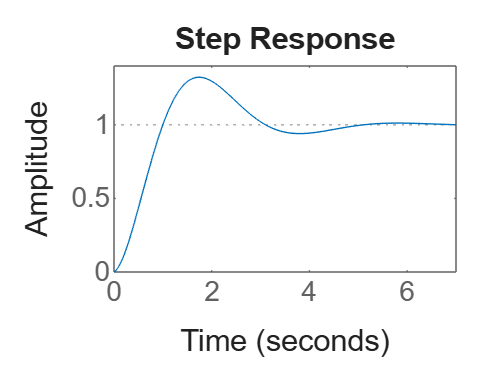

Kz=(kp+ki*Ts/2*(z+1)/(z-1)+kd*1/(1/wc+(Ts/2*(z+1)/(z-1))));
GCLz=feedback(Kz*Gz,1);
step(GCLz)

pole(GCLz)

ans =   -0.6663 + 0.0000i
   0.9919 + 0.0155i
   0.9919 - 0.0155i
   0.9839 + 0.0000i



% t=0:Ts:100;
% u=t;
% lsim(GCLz,u,t)

% clear all
% kp=9.3558;
% ki=11.2875;
% kii=20;
% Ts=0.001;
% syms z
% %Kz=(kp+ki*Ts/2*(z+1)/(z-1)+kii*(Ts/2*(z+1)/(z-1))^2)
% %(9.36*z^2)/(z^2 - 2.0*z + 1.0) - (18.7*z)/(z^2 - 2.0*z + 1.0) + 9.35/(z^2 - 2.0*z + 1.0)
% Num=kp*(z-1)^2+ki*Ts/2*(z+1)*(z-1)+kii*(Ts/2*(z+1))^2
% vpa(expand(Num),5)
% Den=(z-1)^2